clear all
close all
clc

A1=2;
A2=2;
A3=2;


L(1) = Link('prismatic','theta',0,'alpha',-pi/2,'a',0,'offset',0);
L(1).qlim = [0 2]; 
L(2) = Link('prismatic','theta',-pi/2,'alpha',-pi/2,'a',0,'offset',A1);
L(2).qlim = [0 2]; 
L(3) = Link('prismatic','theta',0,'alpha',0,'a',0,'offset',A2+A3);
L(3).qlim = [0 2]; 
L

 
L = 
 theta=          0, d=q1, a=          0, alpha=     -1.571, offset=          0 (P,stdDH)
 theta=     -1.571, d=q2, a=          0, alpha=     -1.571, offset=          2 (P,stdDH)
 theta=          0, d=q3, a=          0, alpha=          0, offset=          4 (P,stdDH)



%unir links 'eslabones'
robotcartesiano = SerialLink(L,'name','Angular')

 
robotcartesiano = 
 
Angular (3 axis, PPP, stdDH, fastRNE)                            
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|          0|         q1|          0|     -1.571|          0|
|  2|     -1.571|         q2|          0|     -1.571|          2|
|  3|          0|         q3|          0|          0|          4|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


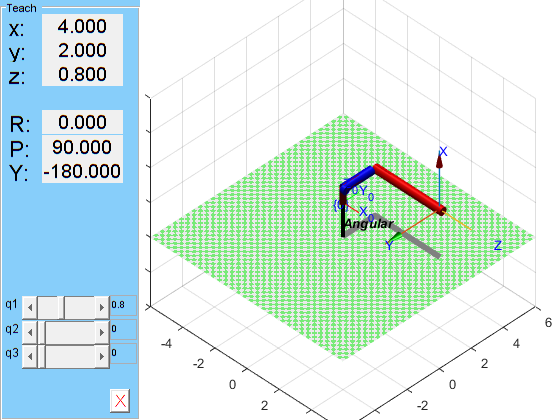


robotcartesiano.tool = transl(0,0,0);


q = [0 0 0 ];  % Ángulos de las articulaciones

% Define el espacio de trabajo (ajusta los valores según sea necesario)
limites_espacio_trabajo = [-7 7 -7 7 -2 7];

robotcartesiano.plot(q, 'workspace', limites_espacio_trabajo);

hold on 
trplot(eye(4),'rgb','length',1,'frame','0') % sistema coordenadas de la base 
axis([-6 6 -6 6 -6 6])% ajusta los ejes 
view(45, 40)% vista frente 
robotcartesiano.teach()